Ligning at kunne

3.28

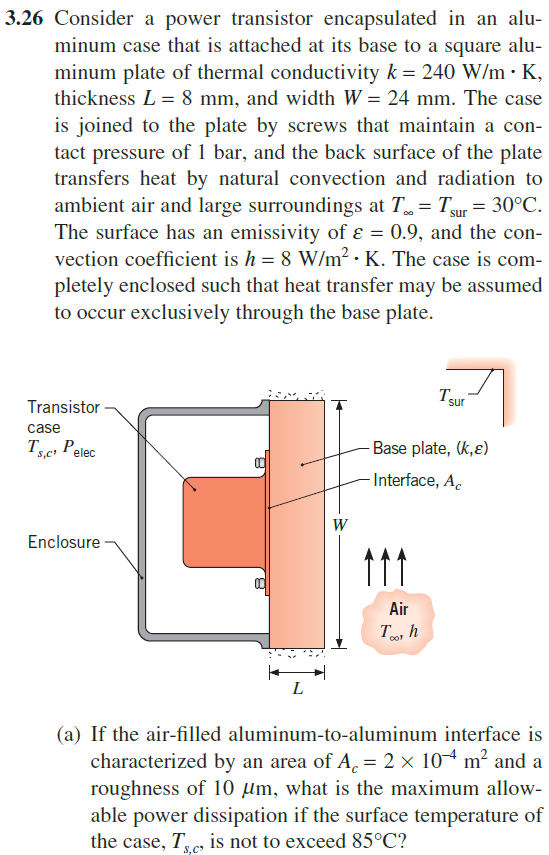

clear all

k = 240; % W/(m*K)
L = 0.008; %m %længde
W = 0.024;%m
T_inf = 30+273.15; % K
T_sur = T_inf;
epsilon = 0.9;
h = 8; % W/(M^2 * K) 
A_plate = W^2; % Area of square plate
A_c =2e-4;
mu = 10e-6;
T_sc = 85 + 273.15; %K
sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
R_tc = 2.75e-4; %m^2 * K/ W % Thermal Resistance fra Table 3.1 side 106 (husk det er 10^-4)

 * A

 * A

Det antages at varmen spredes instantat til hele højden af pladen og derefter går igennem pladen.

Da vi har steady state er q ens igennem alle modstande.

steady state dT/dt = 0 

(1) Steady-state, (2) Negligible heat transfer from the enclosure, to the

surroundings. (3) One-dimensional conduction in the base plate, (4) Radiation exchange at surface of

base plate is with large surroundings, (5) Constant thermal conductivity.

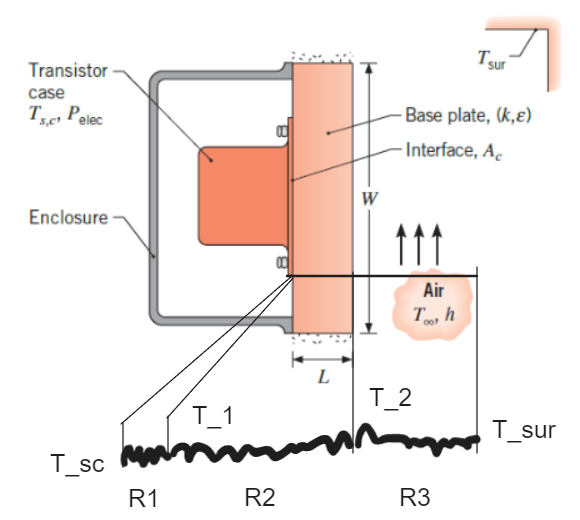

syms T_1 T_2 q T_var
T_2 = sym("T_2", "real");
T_2 = sym("T_2", "positive");


h_r = epsilon * sigma * (T_2 +T_sur) * (T_2^2 +T_sur^2); %ligning 1.9

% q_saml = (T_sc - T_1)/R_tc
% q_cond = -k*A_plate/L * (T_1 - T_2)

R1 = R_tc/A_c %modstanden af plade samlingen
R2 = L/(k *A_plate) %modstanden igennem pladen

Vi samler de to ligninger således vi eliminere $T_1$

q_smal_cond_eq = (T_sc - T_2)/ (R1 + R2);

q_conv = h * A_plate * (T_2 - T_inf);
q_rad = epsilon * sigma * (T_2^4 - T_sur^4) * A_plate; % = h_r * A_plate * (T_2 - T_sur) % 

R3 er paralel forbindelse imellem R3_conv og R3_rad

R3_conv = 1/(h*A_plate);
R3_rad = 1/(h_r*A_plate);
R3 = 1/(1/R3_conv + 1/R3_rad);

q_conv_rad_eq  = q_conv + q_rad % = (T_2 - T_inf)/ R3

Vi siætter de to fundne ligninger lig med hinanden

T_2_sol = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
T_2_sol_ = vpa(T_2_sol, 5)% - 273.75

q = (T_sc - T_sur)/(R1 + R2 + subs(R3, T_2, T_2_sol));

P_elec = vpa(q,5)


h_lin = linspace(4,200, 200-3);
T_2_sol = [];
qs = [];

for i = 1:length(h_lin)
    q_conv = h_lin(i) * A_plate * (T_2 - T_inf);
    q_conv_rad_eq  = q_conv + q_rad; % = (T_2 - T_inf)/ R3

    T_2_sol(i) = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
    % vpa(T_2_sol, 5)% - 273.75
    
    qs(i) = (T_sc - T_sur)/(R1 + subs(R2, h, h_lin(i)) + subs(R3, T_2, T_2_sol(i)));
end

sanity_check_q = qs(5)
sanity_check_h_lin = h_lin(5)

plot(h_lin, T_2_sol, 'DisplayName','T_2 plot')
grid('minor')
% yline(T_sc, 'b--', 'DisplayName','T_sc (K)')
yline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
xline(h,'g--', 'DisplayName','h=8')
xlabel("Varmeovergangs $\alpha$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
ylabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')


plot(T_2_sol, qs, 'DisplayName','q (W) ved T_2')
grid('minor')
xline(double(T_2_sol_), 'b--', 'DisplayName','T_2 ved h=8 (K)')
yline(double(P_elec), 'r--', 'DisplayName','P_elec (W)')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Temperatur $(K)$", Interpreter="latex")
legend('Location','best')


plot(h_lin, qs, 'DisplayName','q (W) ved h')
grid('minor')
xline(h,'g--', 'DisplayName','h=8')
yline(double(P_elec), 'r--', 'r--', 'DisplayName','P_elec (W)')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Varmeovergangs $\alpha$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
legend('Location','best')


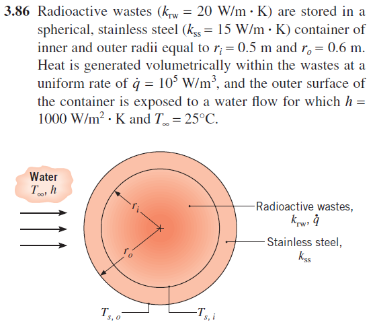

clear all
clf
k_rw = 20; % W/m*K
k_ss = 15; % W/m*K
r_i = 0.5; %m
r_o = 0.6; % m
q_dot = 1e5; % W/m^3
h = 1000; % W/m^2*K
T_inf = 25 + 273.15; % K

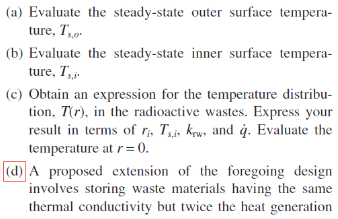

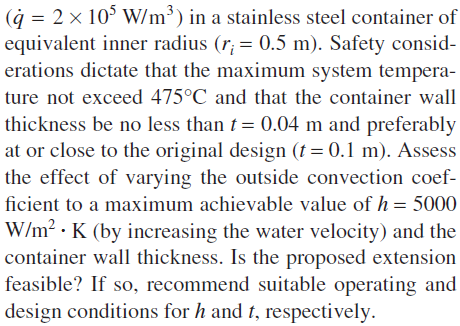

(a)

Bruger Gauss's law  eqvivalent


$$q(r) = \int \dot q\ dV = \dot q  \frac{4}{3} \pi r^3$$


Vi finder T_s,o ved at gå igennem film laget hvor den totale varme der kommer ud er q genneret af kernen

syms T_so T_si
assume(T_so, 'real')

q = q_dot * 4/3 * pi * r_i^3;
A_o = 4*pi*r_o^2;
q_conv = h*A_o *(T_so - T_inf);

T_so_ = solve(q == q_conv, T_so);
T_so = double(vpa(T_so_, 6))
T_so_C = T_so - 273.15

(b)

R_cond =

q = 

q_cond = (T_si - T_so) * 4 * pi * k_ss /(1/r_i - 1/r_o)

T_si_ = solve(q == q_cond, T_si);
T_si = double(vpa(T_si_, 6))
T_si_C = T_si - 273.15

(c)

syms T(r) r T_rw

q_cond_rw = (T_rw - T_si) * 4 * pi * k_rw /(1/r_i - 1/r) %wrong
q_rw = -q_dot * 4/3 * pi * r^3; %wrong


T(r) = solve(q_cond_rw == q_rw, T_rw); %wrong
vpa(T(1),5)
% vpa(T(0.1), 5) - 273.15


rs = linspace(0.00001, 0.499999);
double(T(rs))
plot(rs, double(T(rs)), 'DisplayName','Temp in rw (K)')
grid('minor')
ylabel("Temperatur $(K)$", Interpreter="latex")
xlabel("Radius from mid (m)", Interpreter="latex")
% help legend
legend('Location','southwest')

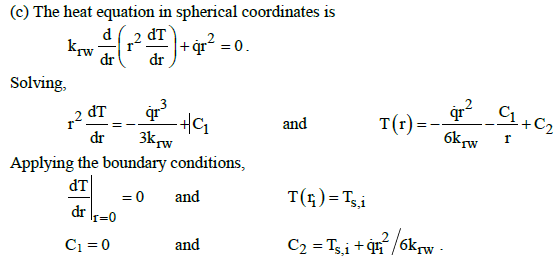

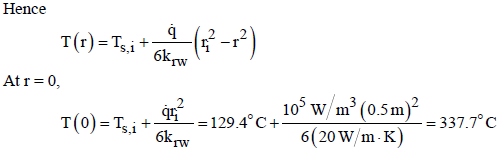

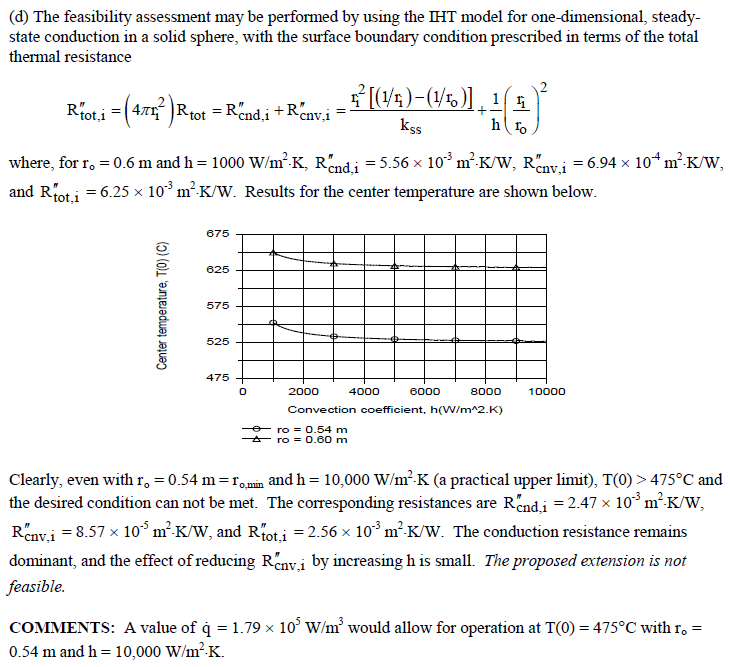

**3.102**

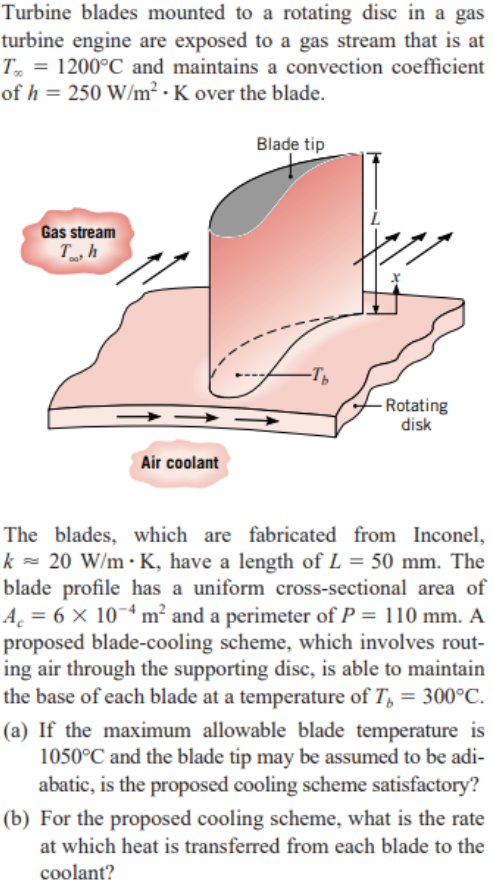

**3.144 (Mangler rigtig version)**

## Eksempler

eksempel 3.4

## Figurer og tabeller

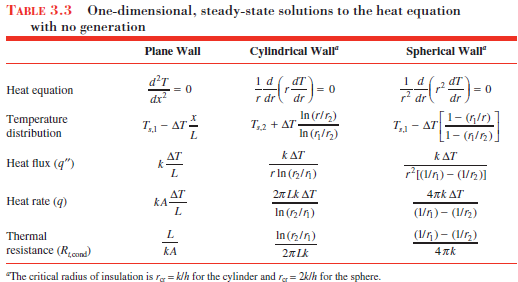

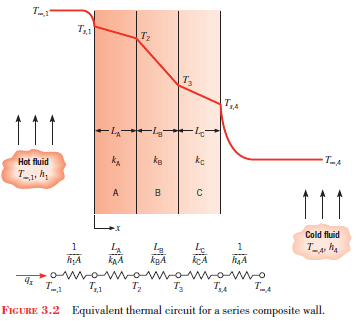

3.22 og sammenhængen til de grå formler 3.103, 3.107, 3.108, 3.109 og 3.110a